# Post Calculations of Ising

## Import data to multidim array

[N_vals,T_vals,data] = importMulti('IsingResultsNew4.tsv');
%remove N=256
data(end,:,:,:)=[];
N_vals(end)=[];
T_vals(:,end)=[];

## Reweight magnetization

data(4,end+1,2,1:1E3)=reweightTemps(data(4,10,1,:),data(4,10,2,:),T_vals(10,4),T_vals(10,4)-0.1);
T_vals(end+1,4)=T_vals(10,4)-0.1;
T_vals(T_vals==0)=nan;

%TODO: temps neu sortieren

## Reduce data to mean and std

[O_mean,O_std,O_var,O_var_err,O_weight,O_corrLength] = ReduceObservableMulti(data);

## Plot energy

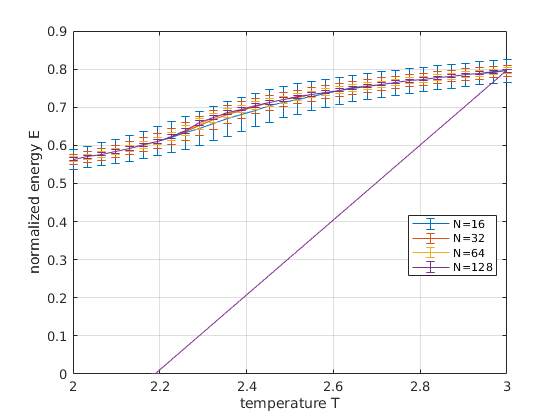

figure(1)
clf
for i=1:size(data,1)
    errorbar(T_vals(:,i),reshape(O_mean(i,:,1,:),[],1), ...
        reshape(O_std(i,:,1,:),[],1),'DisplayName',"N="+N_vals(i))
    hold on
end
grid on
box on
xlabel("temperature T")
ylabel("normalized energy E")
legend("Location","best")

## Plot magnetization

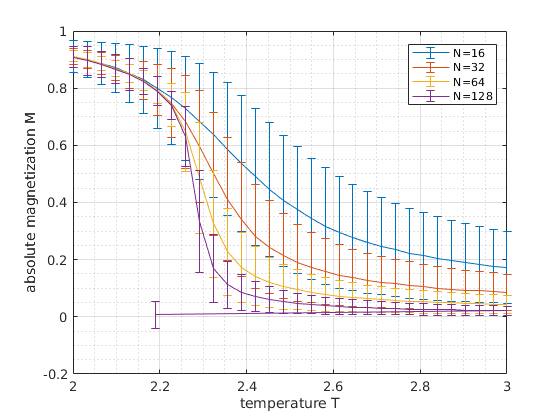

figure(2)
clf
for i=1:size(data,1)
    errorbar(T_vals(:,i),reshape(O_mean(i,:,2,:),[],1), ...
        reshape(O_std(i,:,2,:),[],1),'DisplayName',"N="+N_vals(i))
    hold on
end
grid on
grid minor
box on
xlabel("temperature T")
ylabel("absolute magnetization M")
legend("Location","best")

## heat capacity

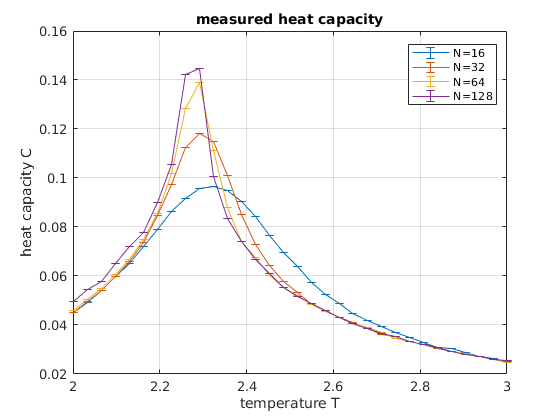

heatCap=reshape(O_var(:,:,1),length(N_vals),[])'.*N_vals.^2./T_vals.^2;
heatCap_err=reshape(O_var_err(:,:,1),length(N_vals),[])'.*N_vals.^2./T_vals.^2;

figure(3)
clf
for i=1:size(data,1)
    errorbar(T_vals(:,i),heatCap(:,i),heatCap_err(:,i),'DisplayName',"N="+N_vals(i))
    hold on
end
grid on
box on
xlabel("temperature T")
ylabel("heat capacity C")
legend("Location","best")
title("measured heat capacity")

Analyse now maxima in log-log-plot and fit a linear equation to the data

ft = fittype( 'poly1' );

% Fit model to data.
[fitHeatCapMax, gof_hcm] = fit( log(N_vals)', log(max(heatCap,[],1))', ft );

Plot

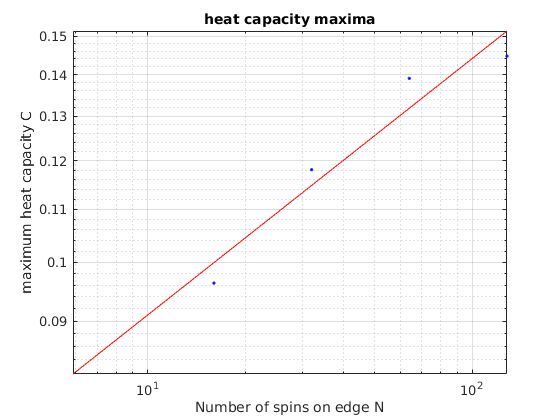

figure(3)
clf
loglog(N_vals,max(heatCap,[],1),'b.','DisplayName',"Data")
hold on
x=linspace(log(N_vals(1))-1,log(N_vals(end)),100);
loglog(exp(x),exp(fitHeatCapMax(x)),'-r','DisplayName',"Fit linear model")
grid on
box on
xlabel("Number of spins on edge N")
ylabel("maximum heat capacity C")
title("heat capacity maxima")

Critical exponent

fitHeatCapMax.p1

ans = 0.1996

hcap_p1_err=table(diff(confint(fitHeatCapMax))/2).Var1(1)

hcap_p1_err = 0.1644

fit exponent

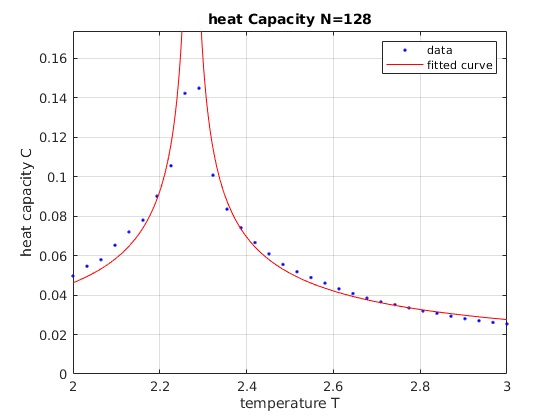

ft = fittype( 'fitHeatCap(T,Tcrit,E0,gamma)', 'independent', 'T');
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf 2.2 -Inf];
opts.StartPoint = [0.1 2.269 -0.5];
opts.Upper = [Inf 2.3 Inf];
opts.Weights = 1./heatCap_err(:,end).^2;

% Fit model to data.
[fitHC_exponent, gof_hc_exponent] = fit( T_vals(:,end), heatCap(:,end), ft, opts );

figure(4)
clf
plot( fitHC_exponent, T_vals(:,end), heatCap(:,end) );
grid on
box on
xlabel("temperature T")
ylabel("heat capacity C")
ylim([0,1.2*max(heatCap(:,end))])
title("heat Capacity N="+N_vals(end))

## susceptibility

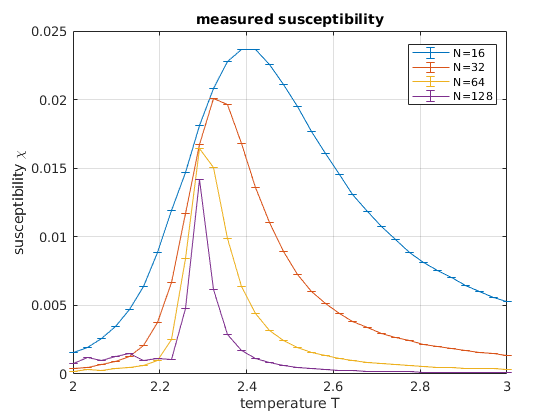

suscept=reshape(O_var(:,:,2),length(N_vals),[])'./T_vals;
suscept_err=reshape(O_var_err(:,:,2),length(N_vals),[])'./T_vals;

figure(5)
clf
for i=1:size(data,1)
    errorbar(T_vals(:,i),suscept(:,i),suscept_err(:,i),'DisplayName',"N="+N_vals(i))
    hold on
end
grid on
box on
xlabel("temperature T")
ylabel("susceptibility \chi")
legend("Location","best")
title("measured susceptibility")

Analyse now maxima in log-log-plot and fit a linear equation to the data

ft = fittype( 'poly1' );

% Fit model to data.
[fitSusceptMax, gof_susc] = fit( log(N_vals)', log(max(suscept,[],1))', ft );

Plot

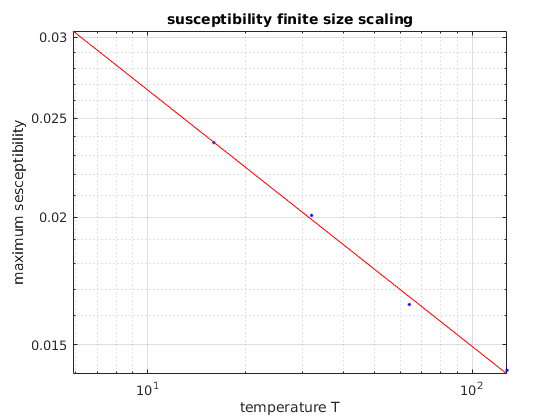

figure(6)
clf
loglog(N_vals,max(suscept,[],1),'b.','DisplayName',"Data")
hold on
x=linspace(log(N_vals(1))-1,log(N_vals(end)),100);
loglog(exp(x),exp(fitSusceptMax(x)),'-r','DisplayName',"Fit linear model")
grid on
box on
xlabel("temperature T")
ylabel("maximum sesceptibility")
title("susceptibility finite size scaling")

Critical exponent

fitSusceptMax.p1

ans = -0.2514

suscept_p1_err=table(diff(confint(fitSusceptMax))/2).Var1(1)

suscept_p1_err = 0.0422

fit exponent

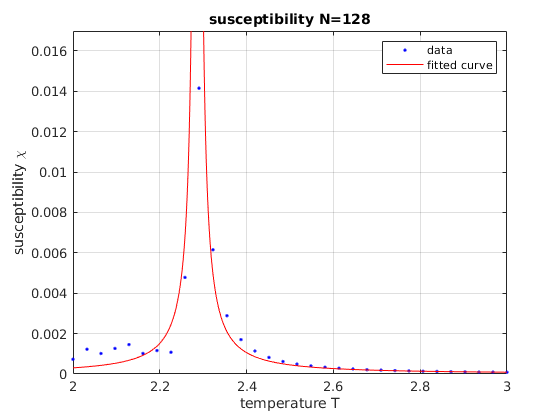

ft = fittype( 'fitHeatCap(T,Tcrit,E0,gamma)', 'independent', 'T');
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf 2.2 -Inf];
opts.StartPoint = [0.1 2.269 -0.5];
opts.Upper = [Inf 2.3 Inf];
opts.Weights = 1./suscept_err(:,end).^2;

% Fit model to data.
[fitSusc_exponent, gof_susc_exponent] = fit( T_vals(:,end), suscept(:,end), ft, opts );

figure(7)
clf
plot( fitSusc_exponent, T_vals(:,end), suscept(:,end) );
grid on
box on
%set(gca,'YScale','log')
xlabel("temperature T")
ylabel("susceptibility \chi")
ylim([0,1.2*max(suscept(:,end))])
title("susceptibility N="+N_vals(end))

exponent is:

fitSusc_exponent.gamma

ans = -1.3469

suscept_gamma_err=table(diff(confint(fitSusc_exponent))/2).Var1(3)

suscept_gamma_err = 0.1066